### 1. Implement Newton’s method (Alg. 2.3). Your signature should be

### function p = newtons(f, fp, p0, tol, maxits)

### where f and fp are function handles and p0, tol, maxits, and p are numbers. (fp is the derivative of f)

=============================================

2. Implement the secant method (Alg. 2.4). Your signature should be

function p = secant(f, p0, p1, tol, maxits)

where f is a function handle and p0, p1, tol, maxits, and p are numbers.

=============================================

3. 

a) f : x -> x^2 - 2

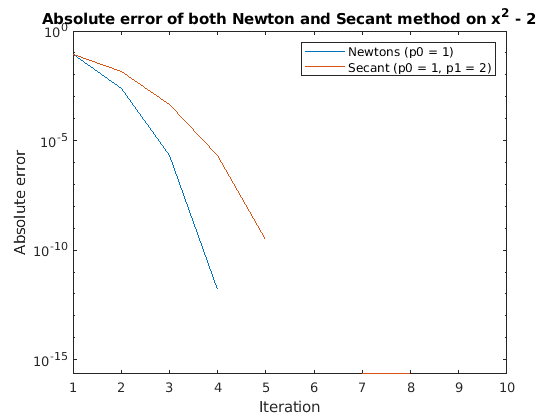

f = @(x) x.^2 - 2;
fp = @(x) 2*x;
[p1, y1] = newtons(f, fp, 1, eps, 10);
[p2, y2] = secant(f, 1, 2, eps, 10);

x1 = linspace(1,numel(y1),numel(y1));
x2 = linspace(1,numel(y2),numel(y2));
for i = 1:numel(y1)
    y1(i) = abs(sqrt(2) - y1(i));
end
for i = 1:numel(y2)
    y2(i) = abs(sqrt(2) - y2(i));
end
semilogy(x1,y1,x2,y2)
xlabel('Iteration');
ylabel('Absolute error');
legend('Newtons (p0 = 1)','Secant (p0 = 1, p1 = 2)');
title('Absolute error of both Newton and Secant method on x^2 - 2');

The reason starting with 0 will break in this case is we are dividing by f'(0) which is 0. Dividing by 0 is a crime in some countries.

b) f : x -> tanh(x)

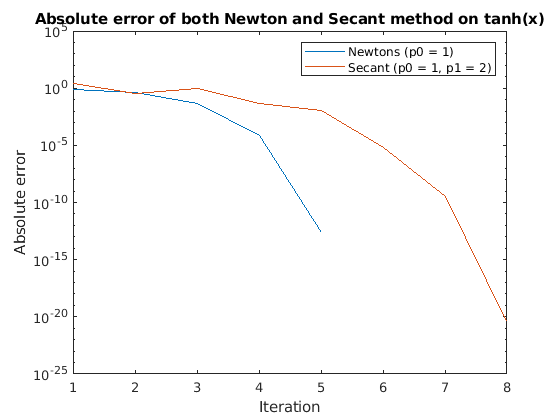

f = @(x) tanh(x);
fp = @(x) sech(x)*sech(x);
[p1, y1] = newtons(f, fp, 1, eps, 10);
[p2, y2] = secant(f, 1, 2, eps, 10);

x1 = linspace(1,numel(y1),numel(y1));
x2 = linspace(1,numel(y2),numel(y2));
for i = 1:numel(y1)
    y1(i) = abs(0 - y1(i));
end
for i = 1:numel(y2)
    y2(i) = abs(0 - y2(i));
end
semilogy(x1,y1,x2,y2)
xlabel('Iteration');
ylabel('Absolute error');
legend('Newtons (p0 = 1)','Secant (p0 = 1, p1 = 2)');
title('Absolute error of both Newton and Secant method on tanh(x)');

They converge when they are roughly closer to 0.

c) f : x^3 -2x + 2

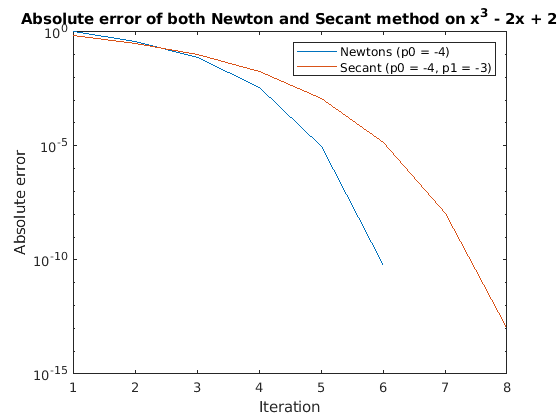

f = @(x) x.^3 - 2*x + 2;
fp = @(x) 3*x.^2 - 2;
[p1, y1] = newtons(f, fp, -4, eps, 10);
[p2, y2] = secant(f, -4, -3, eps, 10);

x1 = linspace(1,numel(y1),numel(y1));
x2 = linspace(1,numel(y2),numel(y2));
for i = 1:numel(y1)
    y1(i) = abs(-1.769292354238631415240409 - y1(i));
end
for i = 1:numel(y2)
    y2(i) = abs(-1.769292354238631415240409 - y2(i));
end
semilogy(x1,y1,x2,y2)
xlabel('Iteration');
ylabel('Absolute error');
legend('Newtons (p0 = -4)','Secant (p0 = -4, p1 = -3)');
title('Absolute error of both Newton and Secant method on x^3 - 2x + 2');

when p0 is equal to 0 or 1, it causes a problem where it tries to give you the complex roots and not the real root.

d) x -> x^(1/3) (nthroot(x,3))

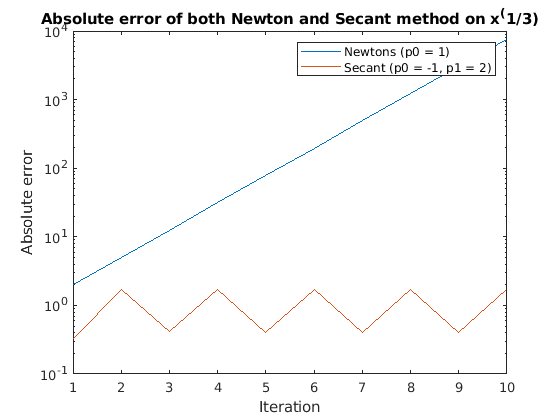

f = @(x) nthroot(x,3);
fp = @(x) x.^(-2/3)/3;
[p1, y1] = newtons(f, fp, 1, eps, 10);
[p2, y2] = secant(f, -1, 2, eps, 10);

x1 = linspace(1,numel(y1),numel(y1));
x2 = linspace(1,numel(y2),numel(y2));
for i = 1:numel(y1)
    y1(i) = abs(0 - y1(i));
end
for i = 1:numel(y2)
    y2(i) = abs(0 - y2(i));
end
semilogy(x1,y1,x2,y2)
xlabel('Iteration');
ylabel('Absolute error');
legend('Newtons (p0 = 1)','Secant (p0 = -1, p1 = 2)');
title('Absolute error of both Newton and Secant method on x^(1/3)');

function [p, y] = newtons(f, fp, p0, tol, maxits)
    p = p0;
    y = 0;
    for i = 1:maxits
        p = p - f(p)/fp(p);
        p = real(p);
        y(i) = p;
        if (abs(f(p)) < tol)
            break
        end
    end
end

function [p, y] = secant(f, p0, p1, tol, maxits)
    P0 = p0;
    P1 = p1;
    y = 0;
    for i = 1:maxits
        p = (P0*f(P1) - P1*f(P0))/(f(P1) - f(P0));
        P0 = P1;
        P1 = p;
        y(i) = p;
        if (abs(f(p)) < tol)
            break
        end
    end
end